# Static M1S7Rx disturbance test

The center segment of M1 is 10urad tilted along the x-axis. At **t=0.1s**, the global TT feedback control is enabled. Then, at approximately **t=0.25**, we turn on the feedforward controller based on the M1ES measurements. There are two datasets, one with the reconstructor obtained through the truncated SVD inversion of the M1ES interaction matrix (TSVD rec) and another considering the inverse of an interaction matrix composed of columns corresponding to the outer axis segments (OAseg rec).

## Summary of the results

The results show that starting with an Rx-tilt in the M1 center segment (which also produces a residual global tilt at the exit pupil), first, most of the segment TT loop correction is an M2 center segment motion compensating for the M1 error. However, one can also notice a minor turn of the outer axis segments, increasing the global tilt at the exit pupil. After enabling the global TT feedback controller at t~0.1s, the global tilt is corrected, and a segment piston is induced (see segment piston plots) until t=0.25s, when the FF command, based on the ES measurement, accounts for the piston error.

One can notice that the reconstructors lead to different behavior. While the feedforward based on the OAseg reconstructor affects the tilt of all the M2 outer segments, in this case, the TSVD reconstructor mainly affects the center segment (refer to the plots with M2-RBM projected onto the segment Rx at the pupil).

## Load LOM data

filename1 = fullfile(im.lfFolder,'ceo-data','lom_tt_dt.mat');
load(filename1,'D_seg_tt');
fprintf('\nTT sensitivity matrix loaded from \n%s\n',filename1);


TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/lom_tt_dt.mat


filename2 = fullfile(im.lfFolder,'ceo-data','D_seg_piston_dt.mat');
load(filename2,'D_seg_piston');
fprintf('Piston sensitivity matrix loaded from \n%s\n',filename2);

Piston sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/D_seg_piston_dt.mat


filename3 = fullfile(im.lfFolder,'ceo-data','rbm2gtt.mat');
load(filename3,'rbm2gtt');
fprintf('Global TT sensitivity matrix loaded from \n%s\n',filename3);

Global TT sensitivity matrix loaded from 
/Users/rromano/Workspace/gmt-data/ceo-data/rbm2gtt.mat


Ts = 1/8e3;     % Simulation sampling period

## Results for each M1 RBM reconstructors (using edge sensors)

fprintf('TSVD M1RBM reconstructor');

TSVD M1RBM reconstructor

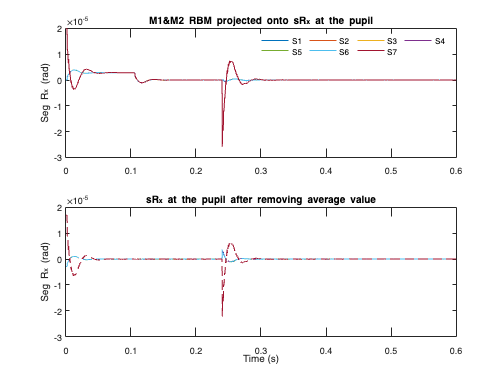

load("m1s7Rx_ltao_test_m1_tsvdREC.mat","m1rbm_dt","m2rbm_dt");

t1 = 0:Ts:(size(m1rbm_dt,1)-1)*Ts;
stt1 = D_seg_tt*[m1rbm_dt,m2rbm_dt]';
gtt1 = rbm2gtt*[m1rbm_dt,m2rbm_dt]';
m2stt1 = D_seg_tt(:,43:84)* m2rbm_dt';
stt_wo_gtt1 = (eye(14) - kron(eye(2),kron(ones(7),1/7))) * stt1;
sp1 = D_seg_piston*[m1rbm_dt,m2rbm_dt]';
sdp1 = sp1 - sp1(7,:);

subplot(211)
plot(t1,stt1(1:7,:)');
title('M1&M2 RBM projected onto sR_x at the pupil');
ylabel('Seg R_x (rad)');
legend('S1','S2','S3','S4','S5','S6','S7',...
    'Orientation','horizontal','NumColumns',4); legend box off;
subplot(212)
plot(t1,stt_wo_gtt1(1:7,:)','--');
title('sR_x at the pupil after removing average value');
ylabel('Seg R_x (rad)');
xlabel('Time (s)')

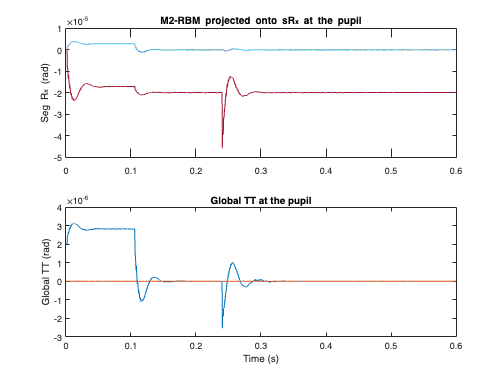

subplot(211); plot(t1,m2stt1(1:7,:)','-');
title('M2-RBM projected onto sR_x at the pupil'); ylabel('Seg R_x (rad)');
subplot(212); plot(t1,gtt1,'-');
xlabel('Time (s)')
ylabel('Global TT (rad)'); title('Global TT at the pupil');

fprintf('OAseg M1RBM reconstructor');

OAseg M1RBM reconstructor

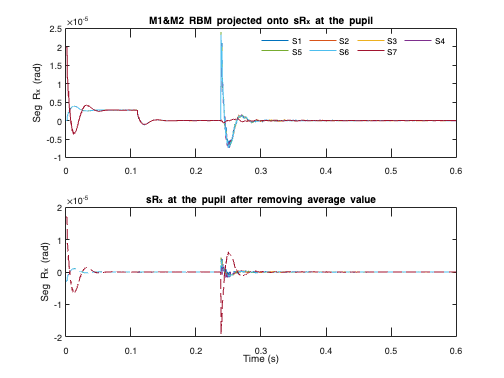

load("m1s7Rx_ltao_test_m1_oaREC.mat","m1rbm_dt","m2rbm_dt");
t2 = 0:Ts:(size(m1rbm_dt,1)-1)*Ts;
stt2 = D_seg_tt*[m1rbm_dt,m2rbm_dt]';
gtt2 = rbm2gtt*[m1rbm_dt,m2rbm_dt]';
m2stt2 = D_seg_tt(:,43:84)* m2rbm_dt';
stt_wo_gtt2 = (eye(14) - kron(eye(2),kron(ones(7),1/7))) * stt2;
sp2 = D_seg_piston*[m1rbm_dt,m2rbm_dt]';
sdp2 = sp2 - sp2(7,:);

subplot(211)
plot(t2,stt2(1:7,:)');
title('M1&M2 RBM projected onto sR_x at the pupil');
ylabel('Seg R_x (rad)');
legend('S1','S2','S3','S4','S5','S6','S7',...
    'Orientation','horizontal','NumColumns',4); legend box off;

subplot(212)
plot(t2,stt_wo_gtt2(1:7,:)','--');
title('sR_x at the pupil after removing average value');
ylabel('Seg R_x (rad)');
xlabel('Time (s)')

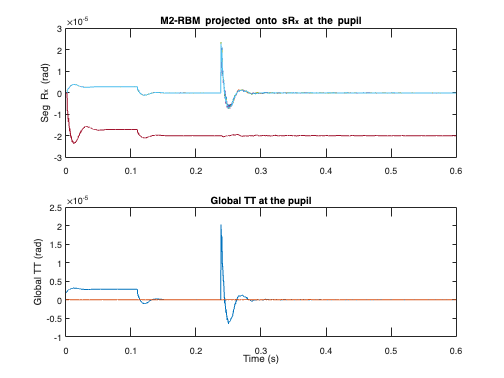

subplot(211); plot(t2,m2stt2(1:7,:)','-');
title('M2-RBM projected onto sR_x at the pupil'); ylabel('Seg R_x (rad)');
subplot(212); plot(t2,gtt2,'-');
xlabel('Time (s)')
ylabel('Global TT (rad)'); title('Global TT at the pupil');

## Comparison plots

### Pupil segment Rx, global TT, and M2RBM induced seg Rx

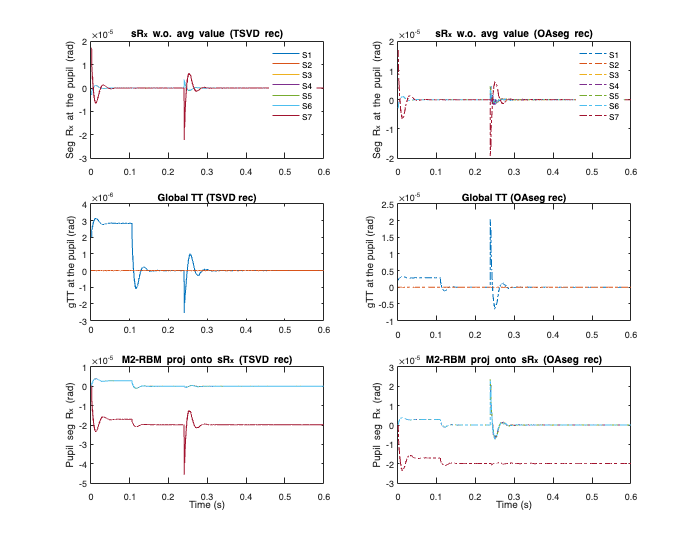

figure; set(gcf,'Position',[833   323   900   700]);%360   277   560   420
% seg Rx (tip)
subplot(321)
plot(t1,stt_wo_gtt1(1:7,:)','-');
title('sR_x w.o. avg value (TSVD rec)');
ylabel('Seg R_x at the pupil (rad)');
legend('S1','S2','S3','S4','S5','S6','S7'); legend box off;
subplot(322)
plot(t2,stt_wo_gtt2(1:7,:)','-.');
title('sR_x w.o. avg value (OAseg rec)');
ylabel('Seg R_x at the pupil (rad)');
legend('S1','S2','S3','S4','S5','S6','S7'); legend box off;
% gTT
subplot(323)
plot(t1,gtt1,'-');
ylabel('gTT at the pupil (rad)'); title('Global TT (TSVD rec)');
subplot(324)
plot(t2,gtt2,'-.');
ylabel('gTT at the pupil (rad)'); title('Global TT (OAseg rec)');
% Segment Rx correction induced by M2-RBM
subplot(325)
plot(t1,m2stt1(1:7,:)','-');
title('M2-RBM proj onto sR_x (TSVD rec)'); ylabel('Pupil seg R_x (rad)'); xlabel('Time (s)')
subplot(326)
plot(t2,m2stt2(1:7,:)','-.');
title('M2-RBM proj onto sR_x (OAseg rec)'); ylabel('Pupil seg R_x (rad)'); xlabel('Time (s)')

### Segment piston

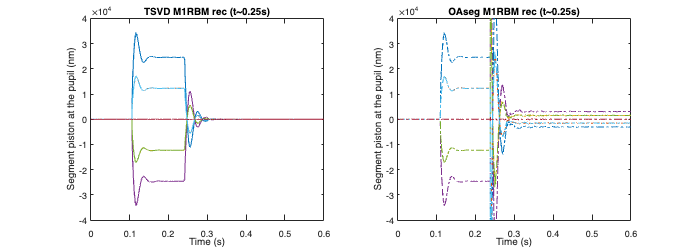

figure; set(gcf,'Position',[833   323   900   320]);%360   277   560   420
subplot(121)
plot(t1,1e9*sp1,'-')
vlim = ylim; xlabel('Time (s)'); ylabel('Segment piston at the pupil (nm)');
title('TSVD M1RBM rec (t~0.25s)')
subplot(122)
plot(t1,1e9*sp2,'-.')
ylim(vlim); % Keeps the same axis limits of left-hand plot.
xlabel('Time (s)'); ylabel('Segment piston at the pupil (nm)');
title('OAseg M1RBM rec (t~0.25s)')

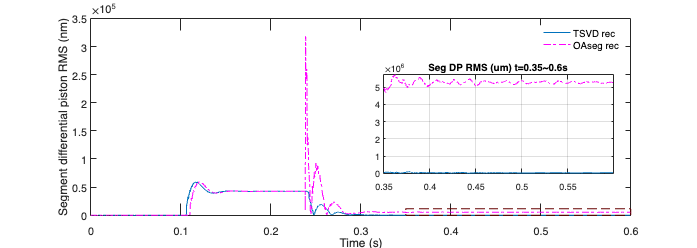

figure; set(gcf,'Position',[833   323   900   320]);%360   277   560   420
subplot(111)
sdp1_rms = 1e9*sqrt(sum(sdp1.^2,1));
sdp2_rms = 1e9*sqrt(sum(sdp2.^2,1));
plot(t1,sdp1_rms,'-',t2,sdp2_rms,'m-.');
set(gca,'Fontsize',12)
xlabel('Time (s)'); ylabel('Segment differential piston RMS (nm)');
legend('TSVD rec','OAseg rec'); legend box off;
%
t_range = round((0.35/Ts):(0.6/Ts));
x1 = t1(t_range(1));
y1 = 0;
dx = t1(t_range(end))-t1(t_range(1));
dy = max([sdp1_rms(t_range),sdp2_rms(t_range)]);

r = rectangle('Position',[x1,y1,dx,2*dy],'EdgeColor',[.4 0 0]);
r.LineStyle = '--';
% create a new pair of axes inside current figure
axes('position',[.55 .3 .33 .4])
box on % put box around new pair of axes
plot(t1(t_range),1e3*sdp1_rms(t_range),'-',t2(t_range),1e3*sdp2_rms(t_range),'m-.');
xlim([x1, x1+dx]); ylim(1e3*[y1, y1+dy]);
title(sprintf('Seg DP RMS (um) t=%.2g~%.2gs',x1,x1+dx));
grid on; hold off;